# Cleaning Workspace

clear;
close all;
clc;

# Initialization Parameters

## Ploting Parameters

linewidth  = 2;
fontname   = 'Times New Roman';
fontsize   = 20;
markersize = 10;

colors = [0.0000 0.0000 0.0000;
          0.0000 0.4470 0.7410;
          0.8500 0.3250 0.0980;
          0.9290 0.6940 0.1250;
          0.4940 0.1840 0.5560;
          0.4660 0.6740 0.1880;
          0.3010 0.7450 0.9330;
          0.6350 0.0780 0.1840];

## FFT Ploting Parameters

N_FFT  = 1024;
freq = 2*pi*linspace(-0.5,0.5,N_FFT);

## Data Transmission Parameters

Parameters related to the data transmission, e.g., number of bits, constellation size, number of subcarriers, and number of transmitted blocks.

B     = 2;                             % Number of bits in a symbol
Q     = 2^B;                           % Constellation size
L     = [10 20 30];                    % Number of users
K     = [16 32 64];                    % Code size
N_BLK = 1000;                          % The number of transmitted data blocks

## Channel Encoder Parameters

R = 0.5;

constraint_length = 7;
tblen = 5*constraint_length;

g0 = 133;
g1 = 165;

state = randi([1 1e6],1,1);

trellis = poly2trellis(constraint_length,[g0 g1]);

## Environment Parameters

Parameters related to the environment noise and the passband multipath channel.

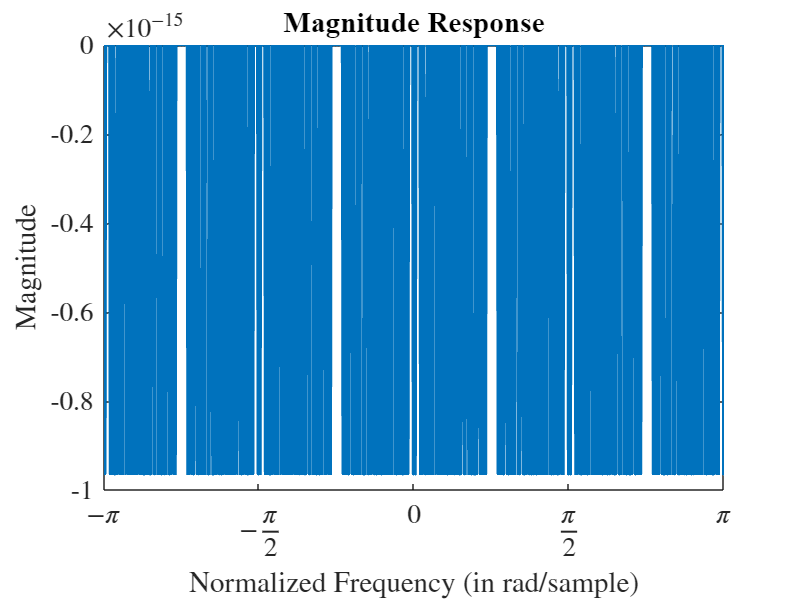

SNR   = -5:10;                        % Signal-to-noise ratio in dB
N_SNR = length(SNR);                  % Length of SNR

% L = 10;                             % Channel's length in samples

% h = randn(L,1) +1i*rand(L,1);

% h = [0.75 0.25]';
h = [0 1]';
% h = [0.75 0.25 0.25]';
% h = [0.75 0.25 0.25 0.5]';

% h = h/norm(h);

h_freq = fft(h,N_FFT);

figure;

set(gcf,'position',[0 0 800 600])

plot(freq,fftshift(20*log10(abs(h_freq))),'linewidth',linewidth,'markersize',markersize);

title('Magnitude Response','fontname',fontname,'fontsize',fontsize);

xlabel('Normalized Frequency (in rad/sample)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('Magnitude','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

xticks([-pi -pi/2 0 pi/2 pi]);

xlim([-pi,pi]);

set(gca,'ticklabelinterpreter','latex', ...
    'xticklabel',{'$-\pi$','$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$','$\pi$'}, ...
    'fontname',fontname,'fontsize',fontsize);

# CDMA Communication System

## Transmitter

BER     = zeros(N_SNR,length(L),length(K));
BER_mpf = zeros(N_SNR,length(L),length(K));

for l_idx = 1:length(L)
    m_bit     = randi([0 1],B*L(l_idx)*N_BLK,1);

    code      = convenc(m_bit,trellis);
    code_itlv = randintrlv(code,state);

    m_mod     = qammod(code_itlv,Q,'gray','InputType','bit');    % Q-QAM modulation
    m_mod     = reshape(m_mod,L(l_idx),[]);

    for k_idx = 1:length(K)
    
        code_cdma = hadamard(K(k_idx));
            
        if L(l_idx) <= K(k_idx)
            x = code_cdma(:,1:L(l_idx))*m_mod;
            x = reshape(x,[],1);

            Px = norm(x)^2/length(x);                            % Average transmission power

## Channel

             z = fftfilt(h,x);                                   % Filter signal by channel

## Receiver

            for snr_ind = 1:N_SNR    
                v  = randn(length(x),1) + 1i*randn(length(x),1); % AWGN noise
                Pv = norm(v)^2/length(v);                        % Average noise power
    
                v  = sqrt(((Px/Pv))*(10^(-SNR(snr_ind)/10)))*v;  % True AWGN noise

                y = x + v;                                       % Received signal without multipath fading
                y = reshape(y,K(k_idx),[]);
    
                y_mpf = z + v;                                   % Received signal with multipath fading
                y_mpf = reshape(y_mpf,K(k_idx),[]);

                m_mod_hat = reshape(code_cdma(:,1:L(l_idx))'*y,[],1);
                m_hat     = qamdemod(m_mod_hat,Q,'gray','OutputType','bit');

                m_mod_hat_mpf = reshape(code_cdma(:,1:L(l_idx))'*y_mpf,[],1);
                m_hat_mpf     = qamdemod(m_mod_hat_mpf,Q,'gray','OutputType','bit');

                code_hat_deitrlv = randdeintrlv(m_hat,state);
                m_bit_hat        = vitdec(code_hat_deitrlv,trellis,tblen,'trunc','hard');

                code_hat_deitrlv_mpf = randdeintrlv(m_hat_mpf,state);
                m_bit_hat_mpf        = vitdec(code_hat_deitrlv_mpf,trellis,tblen,'trunc','hard');

                BER(snr_ind,l_idx,k_idx) = sum(sum(abs(m_bit(:)-m_bit_hat(:))))/length(m_bit_hat(:));
                BER_mpf(snr_ind,l_idx,k_idx) = sum(sum(abs(m_bit(:)-m_bit_hat_mpf(:))))/length(m_bit_hat_mpf(:));
            end
        end
    end
end

# Ploting Results

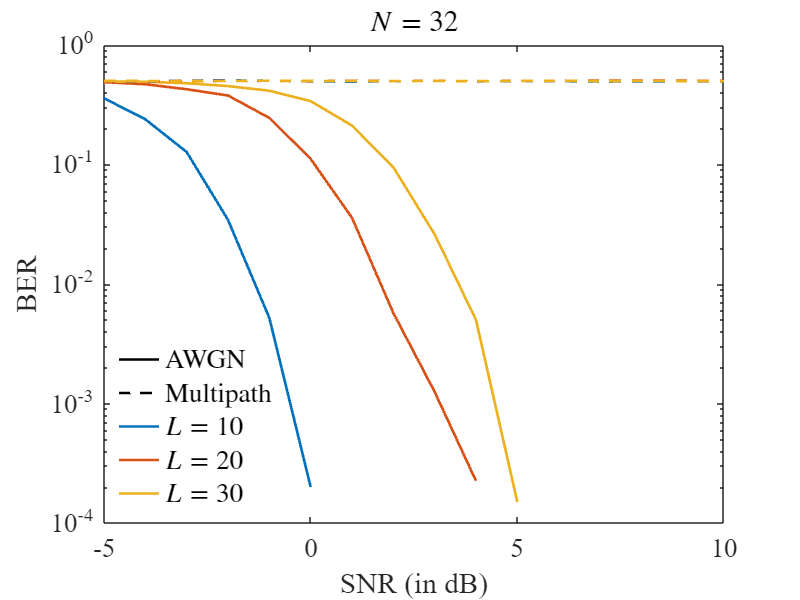

figure;

set(gcf,'position',[0 0 800 600])

semilogy(SNR,BER(:,1,2)    ,'-' ,'color',colors(1,:),'linewidth',linewidth);
hold on;
semilogy(SNR,BER_mpf(:,1,2),'--','color',colors(1,:),'linewidth',linewidth);
semilogy(SNR,BER(:,1,2)    ,'-' ,'color',colors(2,:),'linewidth',linewidth);
semilogy(SNR,BER(:,2,2)    ,'-' ,'color',colors(3,:),'linewidth',linewidth);
semilogy(SNR,BER(:,3,2)    ,'-' ,'color',colors(4,:),'linewidth',linewidth);
semilogy(SNR,BER_mpf(:,1,2),'--','color',colors(2,:),'linewidth',linewidth);
semilogy(SNR,BER_mpf(:,2,2),'--','color',colors(3,:),'linewidth',linewidth);
semilogy(SNR,BER_mpf(:,3,2),'--','color',colors(4,:),'linewidth',linewidth);

title('$N = 32$','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

xlabel('SNR (in dB)','fontname',fontname,'fontsize',fontsize);
ylabel('BER','fontname',fontname,'fontsize',fontsize);

legend({'AWGN','Multipath','$L = 10$','$L = 20$','$L = 30$'},'fontname',fontname,'fontsize',fontsize,'interpreter','latex','location','southwest')
legend box off

xlim([-5 10]);

set(gca,'fontname',fontname,'fontsize',fontsize);

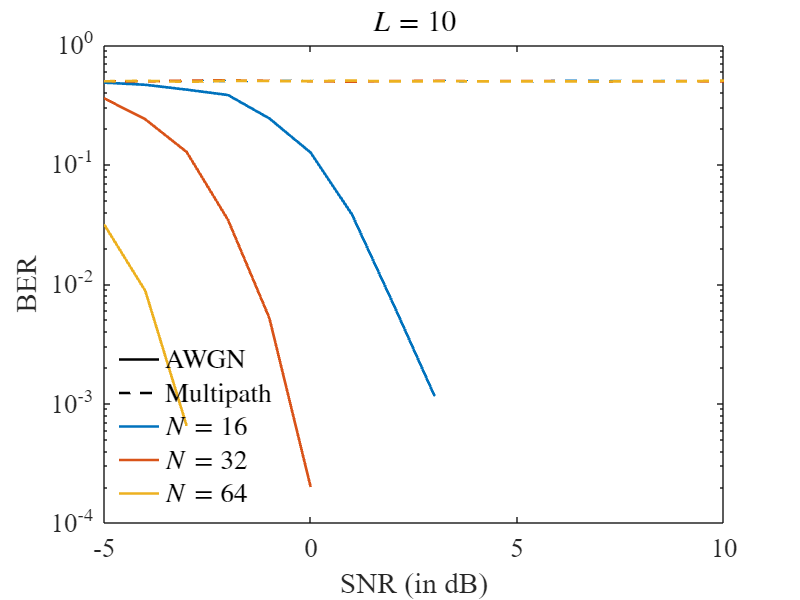

figure;

set(gcf,'position',[0 0 800 600])

semilogy(SNR,BER(:,1,1)    ,'-' ,'color',colors(1,:),'linewidth',linewidth);
hold on;
semilogy(SNR,BER_mpf(:,1,1),'--','color',colors(1,:),'linewidth',linewidth);
semilogy(SNR,BER(:,1,1)    ,'-' ,'color',colors(2,:),'linewidth',linewidth);
semilogy(SNR,BER(:,1,2)    ,'-' ,'color',colors(3,:),'linewidth',linewidth);
semilogy(SNR,BER(:,1,3)    ,'-' ,'color',colors(4,:),'linewidth',linewidth);
semilogy(SNR,BER_mpf(:,1,1),'--','color',colors(2,:),'linewidth',linewidth);
semilogy(SNR,BER_mpf(:,1,2),'--','color',colors(3,:),'linewidth',linewidth);
semilogy(SNR,BER_mpf(:,1,3),'--','color',colors(4,:),'linewidth',linewidth);

title('$L = 10$','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

xlabel('SNR (in dB)','fontname',fontname,'fontsize',fontsize);
ylabel('BER','fontname',fontname,'fontsize',fontsize);

legend({'AWGN','Multipath','$N = 16$','$N = 32$','$N = 64$'},'fontname',fontname,'fontsize',fontsize,'interpreter','latex','location','southwest')
legend box off

xlim([-5 10]);

set(gca,'fontname',fontname,'fontsize',fontsize);